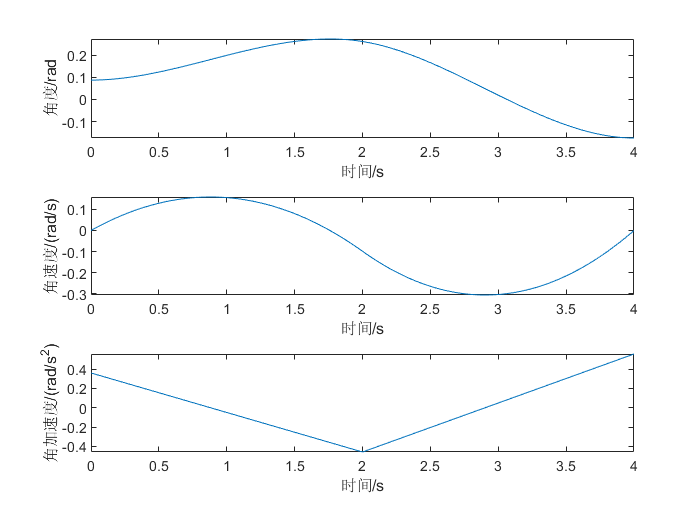

clc, clear, clf;
% 首先计算路径
ts = 0;
t1 = 2; t2 = 2;
tv = t1; 
tf = t1+t2;
theta_s = 5 * pi/180; 
theta_v = 15 * pi/180;
theta_f = -10 * pi/180;

P = [
    1   ts  ts^2    ts^3    0   0   0       0       % 起始时刻的位置
    0   1   2*ts    3*ts^2  0   0   0       0       % 起始时刻速度
    1   tv  tv^2    tv^3    0   0   0       0       % 中间时刻的位置
    0   0   0       0       1   tv  tv^2    tv^3    % 中间时刻的位置
    0   1   2*tv    3*tv^2  0   -1  -2*tv   -3*tv^2 % 中间时刻的速度相同
    0   0   2       6*tv    0   0   -2      -6*tv   % 中间时刻加速度相同
    0   0   0       0       1   tf  tf^2    tf^3    % 结束时刻的位置
    0   0   0       0       0   1   2*tf    3*tf^2  % 结束时刻的速度
];
T = [
    theta_s     % 起始时刻的位置
    0           % 起始时刻速度
    theta_v     % 中间时刻的位置
    theta_v     % 中间时刻的位置
    0           % 中间时刻的速度相同
    0           % 中间时刻加速度相同
    theta_f     % 结束时刻的位置
    0           % 结束时刻的速度
];
A = P\T;
f1 = @(x) A(1) + A(2)*x + A(3)*x.^2 + A(4)*x.^3;
df1 = @(x) A(2) + 2*A(3)*x + 3*A(4)*x.^2;
ddf1 = @(x) 2*A(3) + 6*A(4)*x;
f2 = @(x) A(5) + A(6)*x + A(7)*x.^2 + A(8)*x.^3;
df2 = @(x) A(6) + 2*A(7)*x + 3*A(8)*x.^2;
ddf2 = @(x) 2*A(7) + 6*A(8)*x;
t1 = 0:0.01:tv;
t2 = tv:0.01:tf;
tt = [t1, t2];
y1 = f1(t1);    y2 = f2(t2);    yy = [y1, y2];
dy1 = df1(t1);    dy2 = df2(t2);    dyy = [dy1, dy2];
ddy1 = ddf1(t1);    ddy2 = ddf2(t2);    ddyy = [ddy1, ddy2];
figure(1)
subplot(3, 1, 1)
plot(tt, yy)
xlabel("时间/s");ylabel("角度/rad")
subplot(3, 1, 2)
plot(tt, dyy)
xlabel("时间/s");ylabel("角速度/(rad/s)")
subplot(3, 1, 3)
plot(tt, ddyy)
xlabel("时间/s");ylabel("角加速度/(rad/s^2)")

若两个关节均按照上述运动

取$m_1 = 10 \text{kg}, m_2 = 5\text{kg}, L_1 = 0.5\text{m}, L_2 = 0.4\text{m}
$

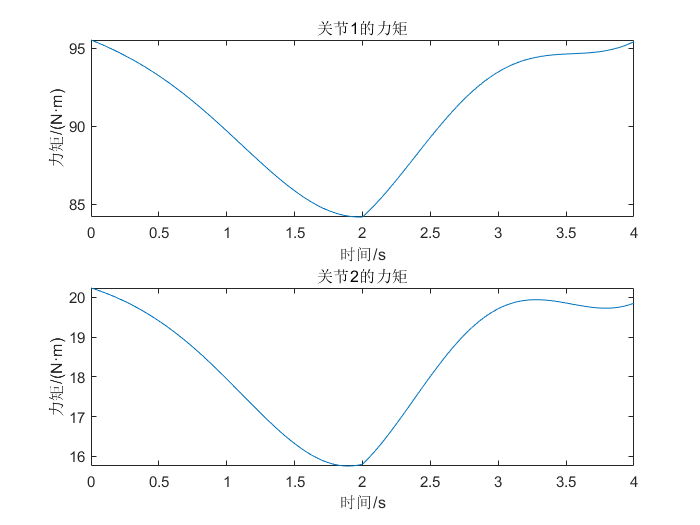

m1 = 10;
m2 = 5;
l1 = 0.5;
l2 = 0.4;

tao1 = m2*l2^2*(ddyy+ddyy) + m2*l1*l2*cos(yy).*(2*ddyy+ddyy) + (m1+m2)*l1^2*ddyy - m2*l1*l2*sin(yy).*dyy.^2 - 2*m2*l1*l2*sin(yy).*dyy.*dyy + m2*l2*9.8*cos(yy+yy) + (m1+m2)*l1*9.8*cos(yy);
tao2 = m2*l1*l2*cos(yy).*ddyy + m2*l1*l2*sin(yy).*dyy.^2 + m2*l2*9.8*cos(yy+yy) + m2*l2*l2*(ddyy+ddyy);
figure(2)
subplot(2, 1, 1)
plot(tt, tao1)
title("关节1的力矩")
xlabel("时间/s");ylabel("力矩/(N·m)")
subplot(2,1,2)
plot(tt, tao2)
title("关节2的力矩")
xlabel("时间/s");ylabel("力矩/(N·m)")

力矩的最大值

[maxtao1, idx1] = max(tao1)

maxtao1 = 95.5242

idx1 = 1

yy(idx1)

ans = 0.0873

[maxtao2, idx2] = max(tao2)

maxtao2 = 20.2368

idx2 = 1

yy(idx2)

ans = 0.0873

由此可见，力矩最大处在$t=0, \theta=5^{\circ}$时，此时加速度最大，关节1的最大力矩为$95.5242 \text{N}\cdot\text{m}$，关节2的最大力矩为$20.2368 \text{N}\cdot\text{m}$